# Playing with correlations and noisy signals

## Simple cross-correlation example:

Lets say we have two sin waves that are exactly in phase. The correlation should be 1: 

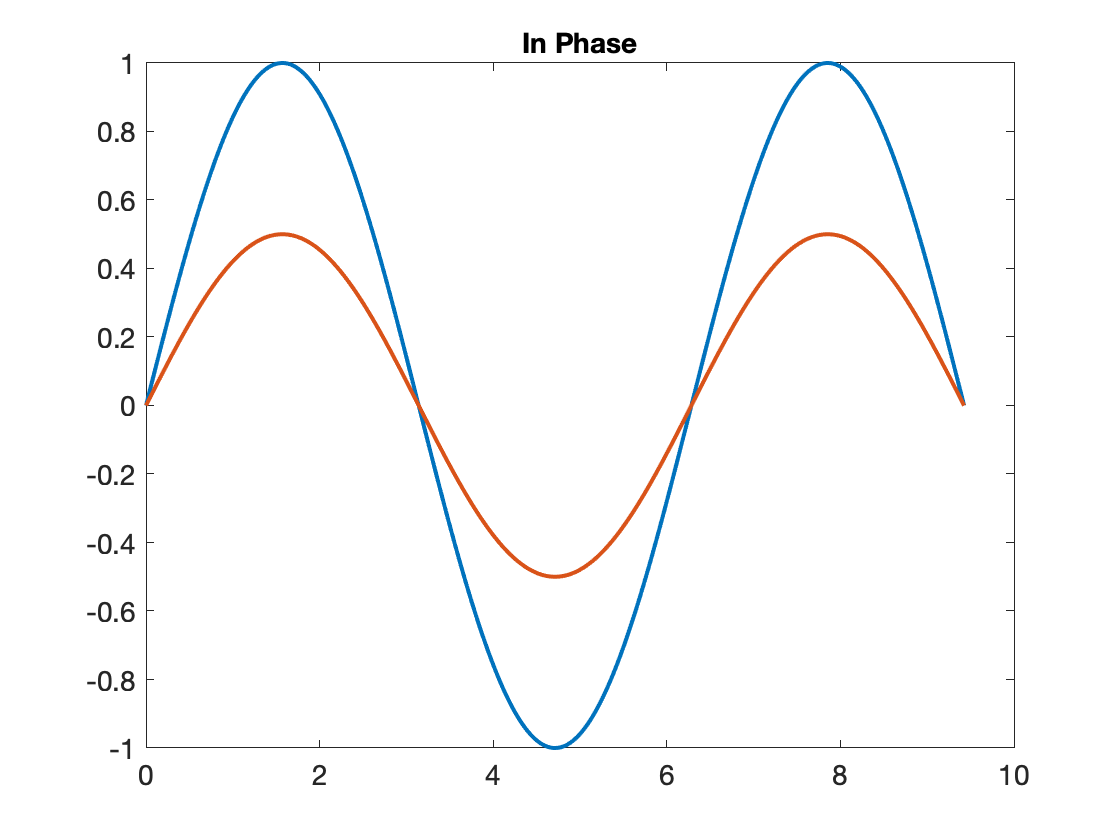

x= linspace(0,3*pi,1000);
y = sin(x);
y1 = sin(x)/2;

figure(1); clf; plot(x,y, x,y1); title('In Phase')

r1= corr(y', y1')

r1 = 1

Now, if they are 1/4 or 1/8 cycle out of phase, you can lose the correlation: 

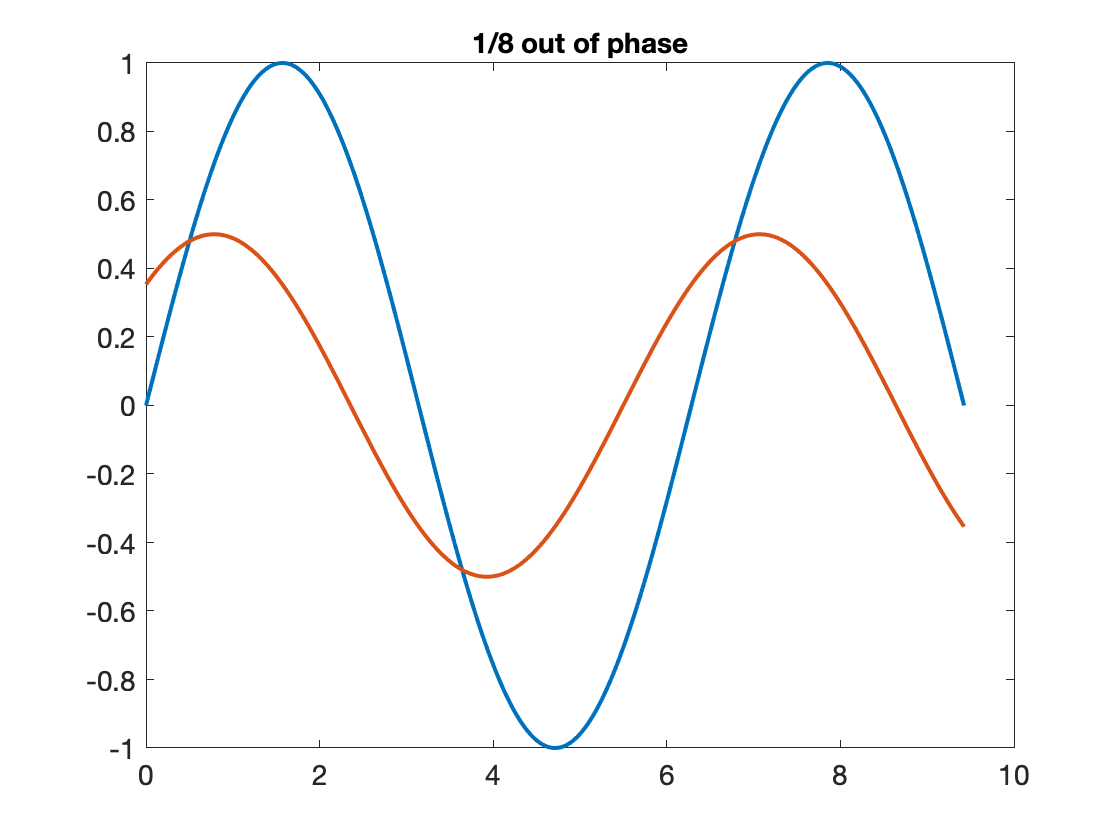

y2 = sin(x+pi/4)/2;
y3 = sin(x+pi/2)/2;

figure(2); clf; plot(x,y, x,y2); title('1/8 out of phase')

r2= corr(y', y2') % 1/8 out of phase

r2 = 0.6899

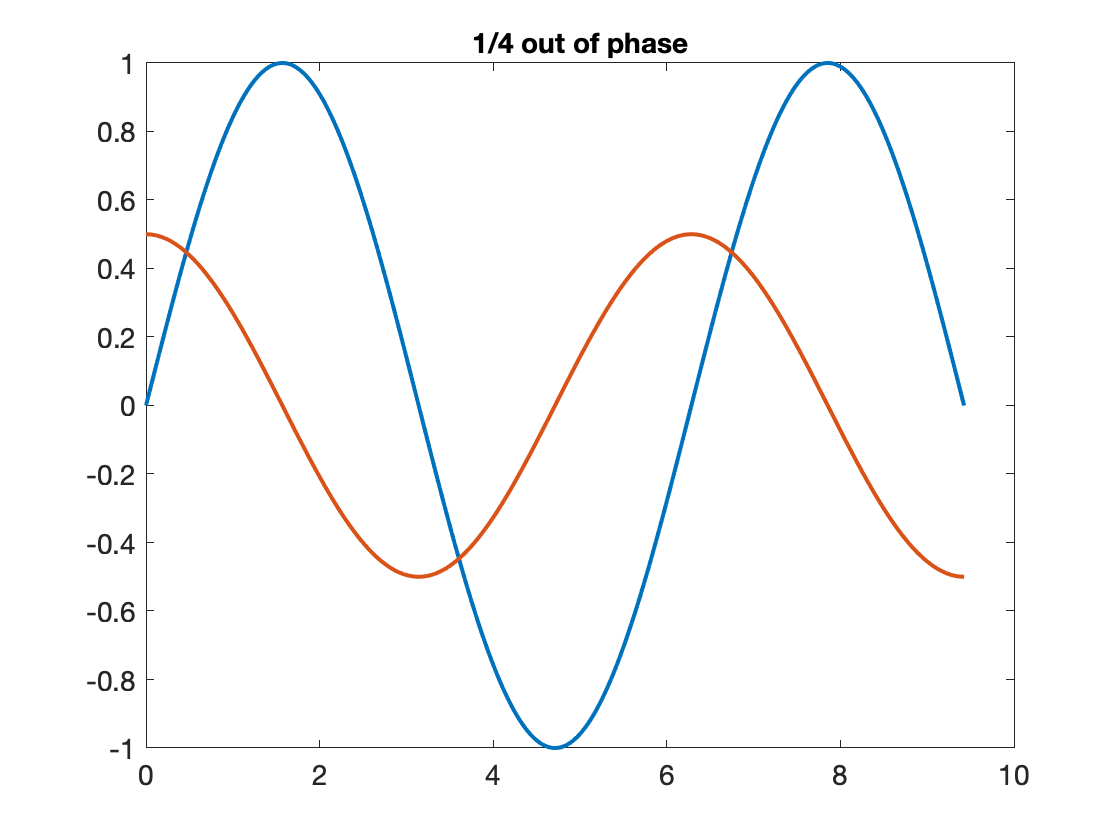


figure(3); clf; plot(x,y, x,y3); title('1/4 out of phase')

r3= corr(y', y3') % 1/4 out of phase

r3 = 3.0143e-17

In real-world data, we may have one signal that we suspect is causing another signal, or one signal may change more quickly in response to a third factor than a second signal. So realistically we might not expect a change to take place immediately in both signals... there may be a lag. Instead, we can look at the cross correlation function "xcorr", which can tell us our correlation as a function of lag bewtween the two signals: 

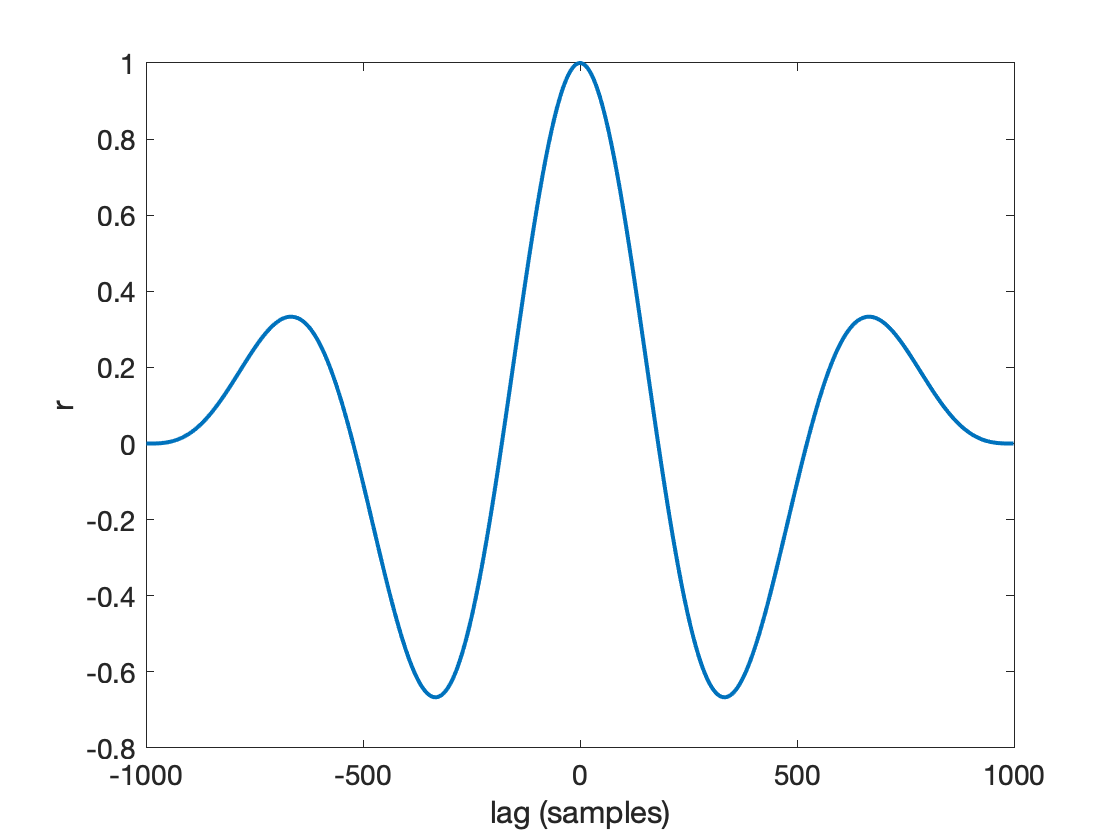

[xc1, lags1] = xcorr(y,y1, 'normalized');
figure(1); clf; plot(lags1,xc1); xlabel('lag (samples)'); ylabel('r'); title('xcorr on the same signal')

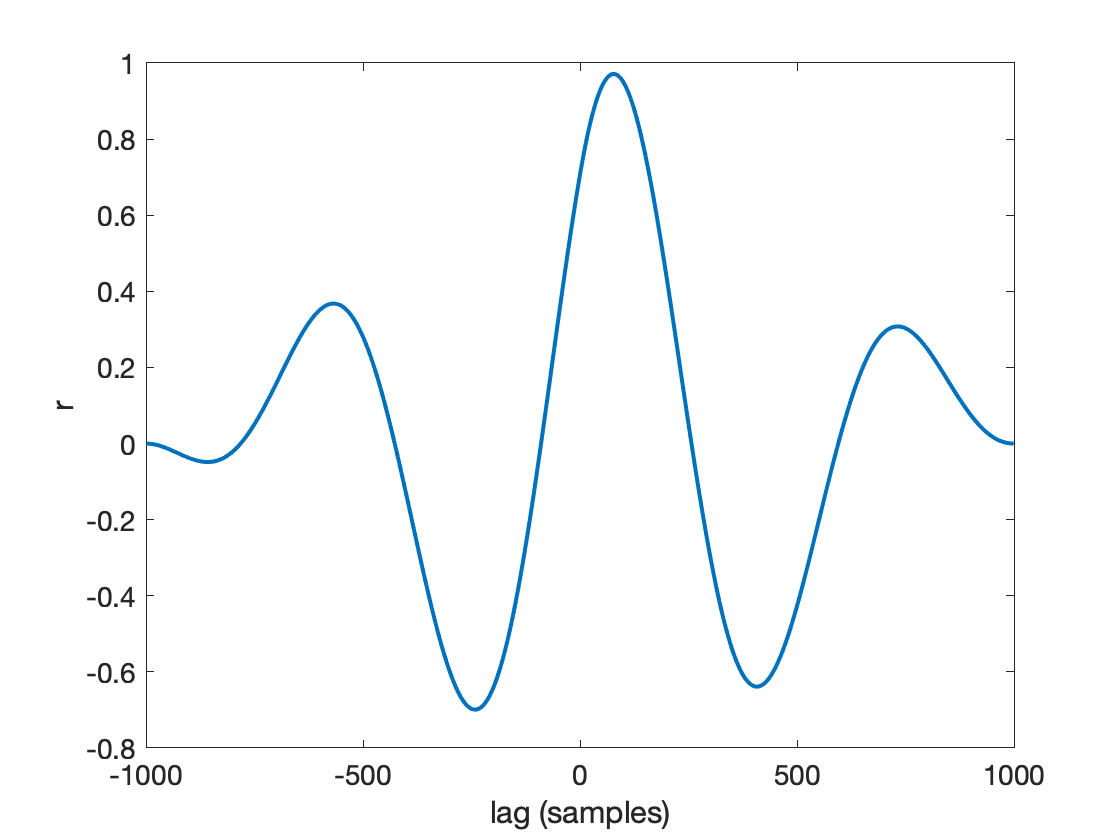


[xc2, lags2] = xcorr(y,y2, 'normalized');
figure(2); clf; plot(lags2,xc2); xlabel('lag (samples)'); ylabel('r');  title('xcorr on sin(x) and sin(x+pi/4)')

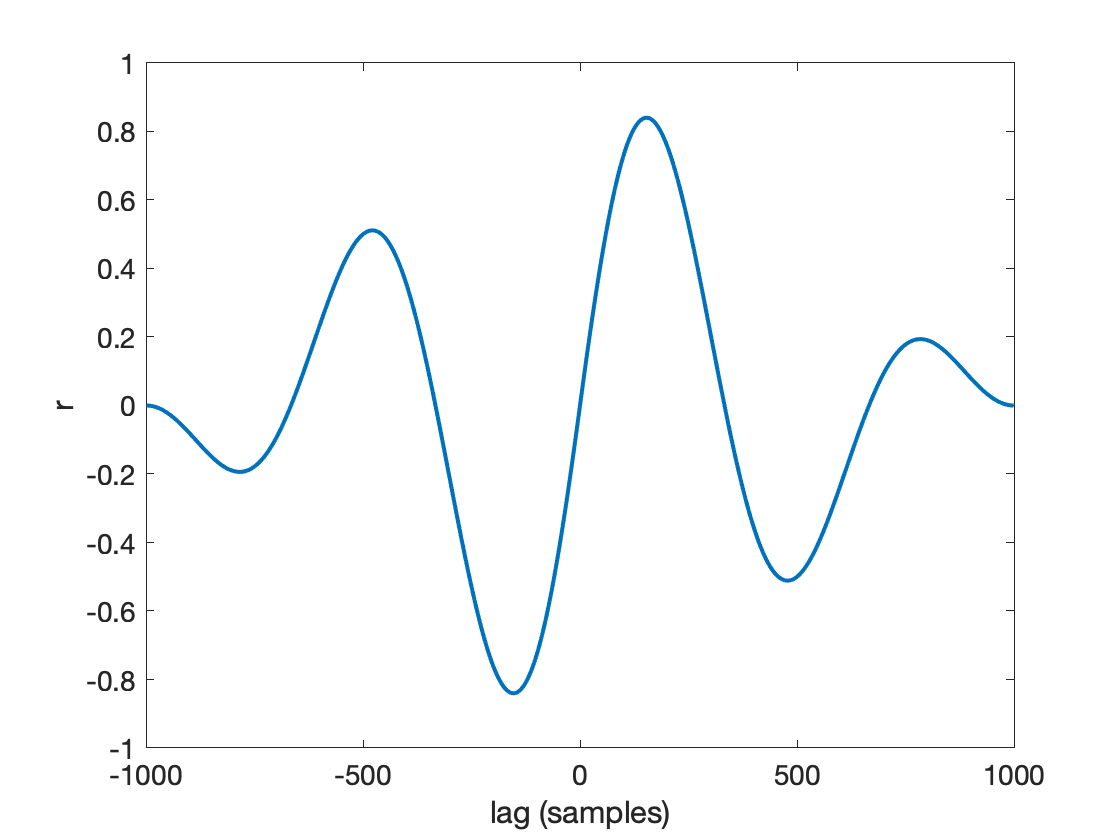


[xc3, lags3] = xcorr(y,y3, 'normalized');
figure(3); clf; plot(lags3,xc3); xlabel('lag (samples)'); ylabel('r'); title('xcorr on sin(x) and sin(x+pi/2)')

(Note: the cross-correlation of a signal with itself is called the "autocorrelation" [auto- Gk. self + correlation] )

As we might expect, the correlation is maximal at +pi/4 and +pi/2 for the shifted cases. As a sanity check, we should see that the correlation at zero lag is the same as the plain "corr" function that we were doing before: 

lag=lags1(round(end/2)) %lag in the middle should be zero. 

lag = 0


% check correlation at index for 0 lag
fprintf('in phase signals, xcorr at zero lag: %d, corr function: %d', xc1(round(end/2)), r1)

in phase signals, xcorr at zero lag: 1.000000e+00, corr function: 1

fprintf('1/8 out of phase signals, xcorr at zero lag: %d, corr function: %d', xc2(round(end/2)), r2)

1/8 out of phase signals, xcorr at zero lag: 7.067531e-01, corr function: 6.898903e-01

fprintf('1/4 out of phase signals, xcorr at zero lag: %d, corr function: %d', xc3(round(end/2)), r3)

1/4 out of phase signals, xcorr at zero lag: 3.673109e-17, corr function: 3.014275e-17

Note that they are actually different! What's going on? Apparently "corr" first subtracts the mean from the signals before performing the correlation. So we can use xcorr in a similar way to get the same answer: 

xc1 = xcorr(y-mean(y),y1-mean(y1), 0,'coeff') %xcorr at 0 lag

xc1 = 1

r1

r1 = 1


xc2 = xcorr(y-mean(y),y2-mean(y2), 0,'coeff')

xc2 = 0.6899

r2

r2 = 0.6899


xc3 = xcorr(y-mean(y),y3-mean(y3), 0,'coeff')

xc3 = 1.2327e-17

r3 % small difference likely due to a rounding error in xcorr estimation 

r3 = 3.0143e-17

Some Thoughts: 

"xcorr" may be more informative than "corr" especially in cases where the signals are cyclic and you have a leading-lagging relationship that makes sense. If both signals were straight lines, then the lag wouldn't matter, and the correlation would be the same no matter what the lag value was. More on this in the next section. 

## Dealing with non-stationary signals

What happens if the data is not cyclic and is increasing (like a line)? If you look in the documentation of xcorr, it says that the cross correlation function estimates the correlation between two "jointly stationary" signals. At a basic level, a stationary signal is one whose mean and variance does not change much over time.... i.e. if you were to slide a window along a sine wave and compute the mean within that window, it would pretty much always be zero. However, if you were to compute the mean in a sliding window along a line, the mean would be increasing with the line. Therefore a sine wave is an example of a stationary signal while a line is "non-stationary". Sometimes you'll see this in mathy papers as the "stationarity condition", though it is more nuanced than what I've presented here (Wikipedia has a nice deeper overview if interested). 

So it seems like xcorr makes most sense when dealing with stationary processes. 

Below is an example using "xcorr" with a line. Because the function pads the signal with zeros when it creates the lag, we get some funky things happening (like the negative correlation) when estimating the correlation for large lags. 

x1 = linspace(1,10);

figure(1); clf;
% Both with and without removing the mean:
lag= 4

lag = 4

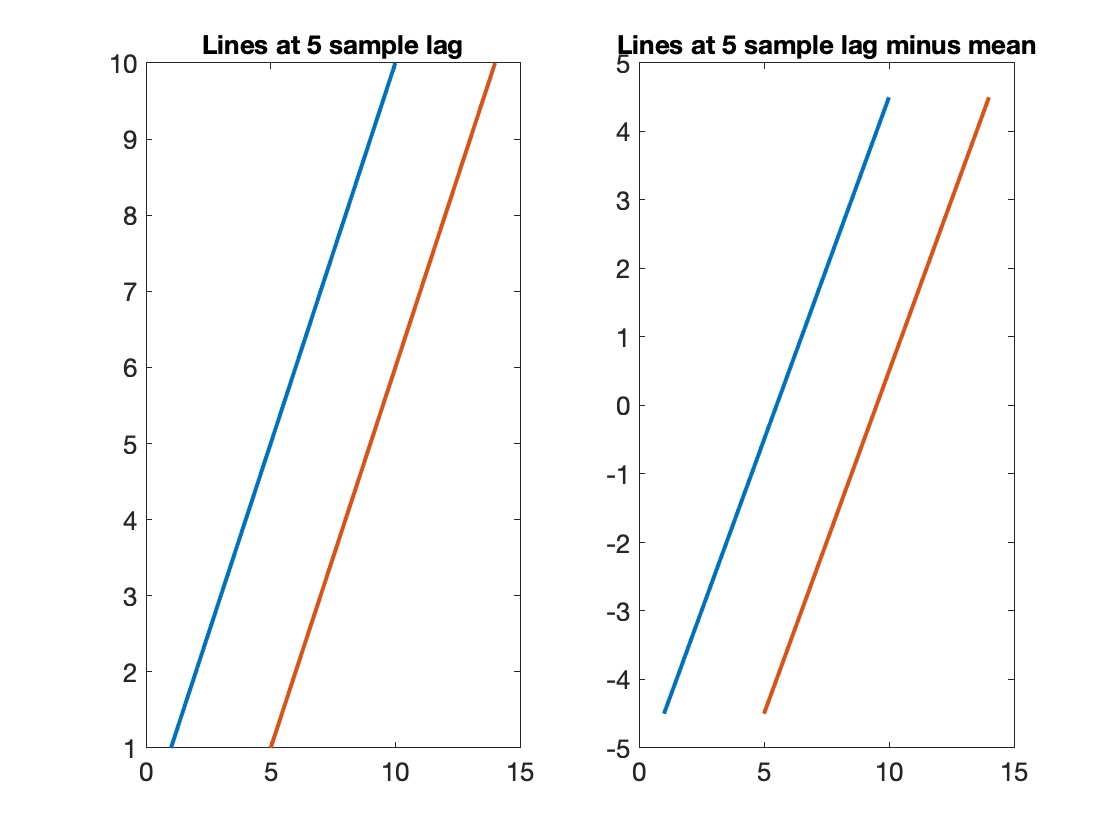

subplot(121); plot(x1, x1, x1+lag, x1); title('Lines at 5 sample lag');
subplot(122); plot(x1, x1-mean(x1), x1+lag, x1-mean(x1)); title('Lines at 5 sample lag minus mean');

laggedcorr= corr(x1', x1'+lag)

laggedcorr = 1

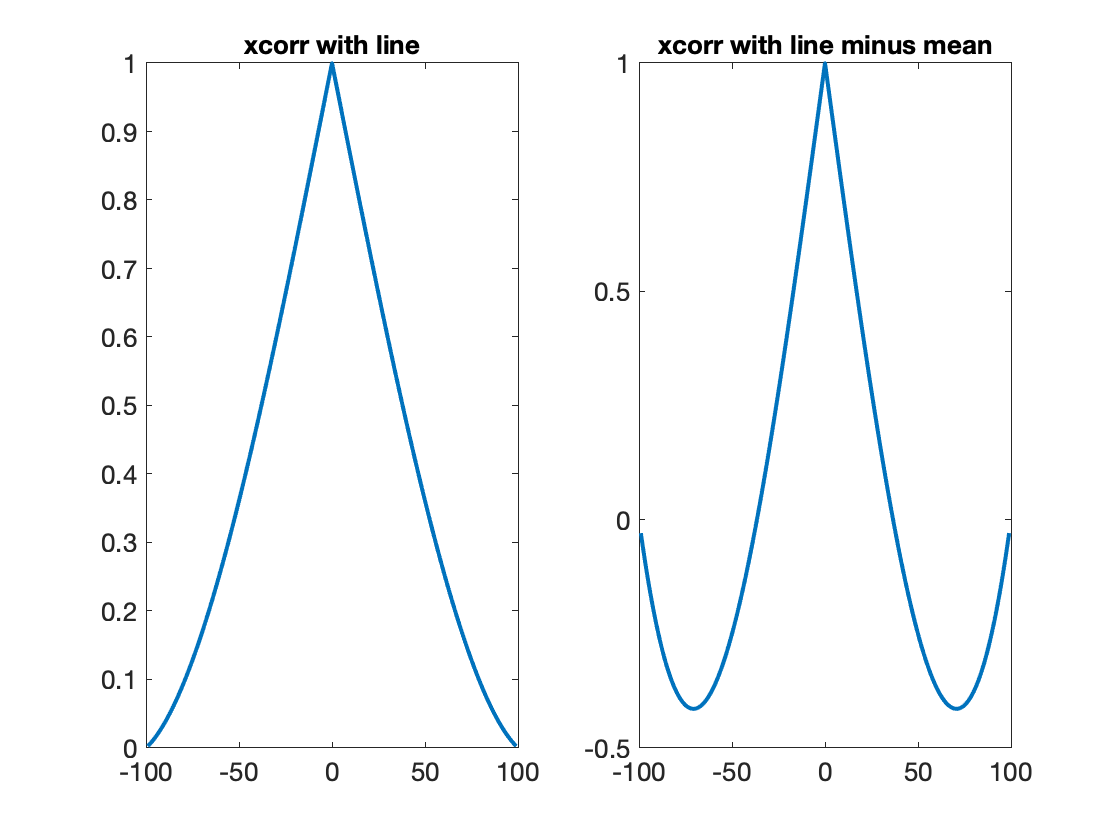


figure(2); clf;
subplot(121)
[xc, lags]=xcorr(x1, x1, 'normalized'); plot(lags, xc); title('xcorr with line')
subplot(122)
[xc, lags]=xcorr(x1-mean(x1), x1-mean(x1), 'normalized'); plot(lags, xc); title('xcorr with line minus mean')

There are some tricks we could play to rectify this if we are really curious about a cyclic lead-lag relationship in a signal that is also increasing. For one thing, we can try to "regress out" the mean of the signal, leaving us with a stationary cyclic "residual" signal. Then we could apply our xcorr function to that:

As an example, say that I have two increasing functions that also has a cyclic nature on top of it (like a line + a sine wave), where the cycles of one fuction lead the other by 1/2 phase:

x=linspace(0,10*pi,100)

x =          0    0.3173    0.6347    0.9520    1.2693    1.5867    1.9040    2.2213    2.5387    2.8560    3.1733    3.4907    3.8080    4.1253    4.4427    4.7600    5.0773    5.3947    5.7120    6.0293    6.3467    6.6640    6.9813    7.2986    7.6160    7.9333    8.2506    8.5680    8.8853    9.2026    9.5200    9.8373   10.1546   10.4720   10.7893   11.1066   11.4240   11.7413   12.0586   12.3760   12.6933   13.0106   13.3280   13.6453   13.9626   14.2800   14.5973   14.9146   15.2320   15.5493


offset = pi/2;
y1= sin(x)*5+sin(3*x)*2+x;
y2= sin(x+offset)*5+sin(3*(x+offset))+x/2;

figure(1); clf; hold on; 
plot(y1); title('complex signals and moving average')
plot(y2);

Let's try to get the mean of the signal for a sliding window of 40 samples and plot that on top of the original signal:

nwind=52

nwind = 52

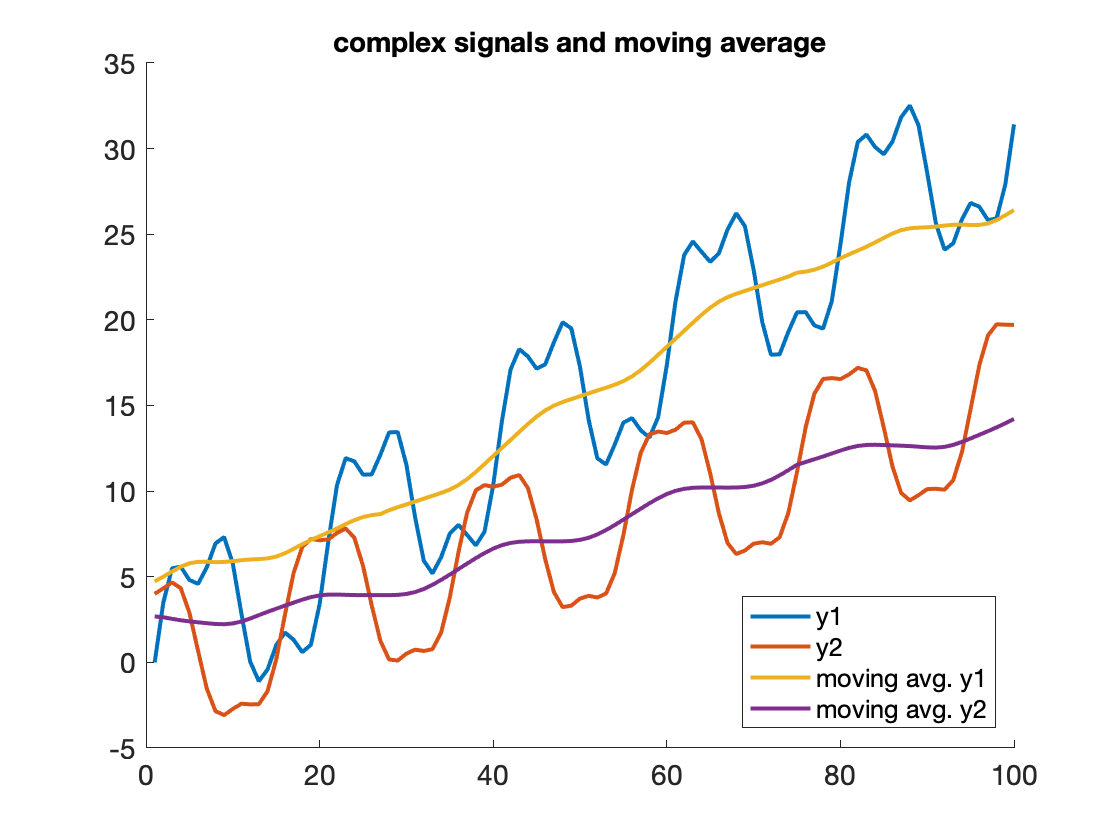

mn_1= movmean(y1, nwind); plot(mn_1)
mn_2= movmean(y2, nwind); plot(mn_2)
legend('y1', 'y2', 'moving avg. y1', 'moving avg. y2', 'location', 'best')

Now we can subtract the mean from the original signal to be left with the stationary sine wave components: 

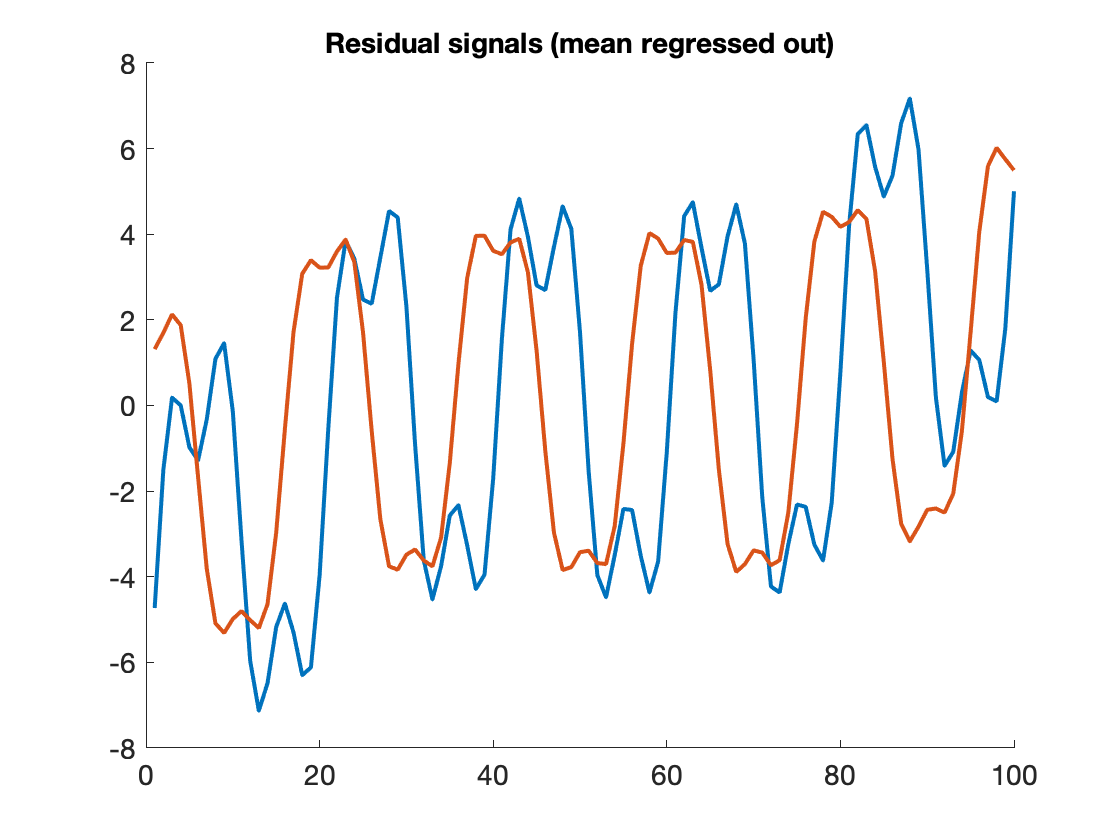

figure(2); clf; hold on;
plot(y1-mn_1); title('Residual signals (mean regressed out)')
plot(y2-mn_2); 

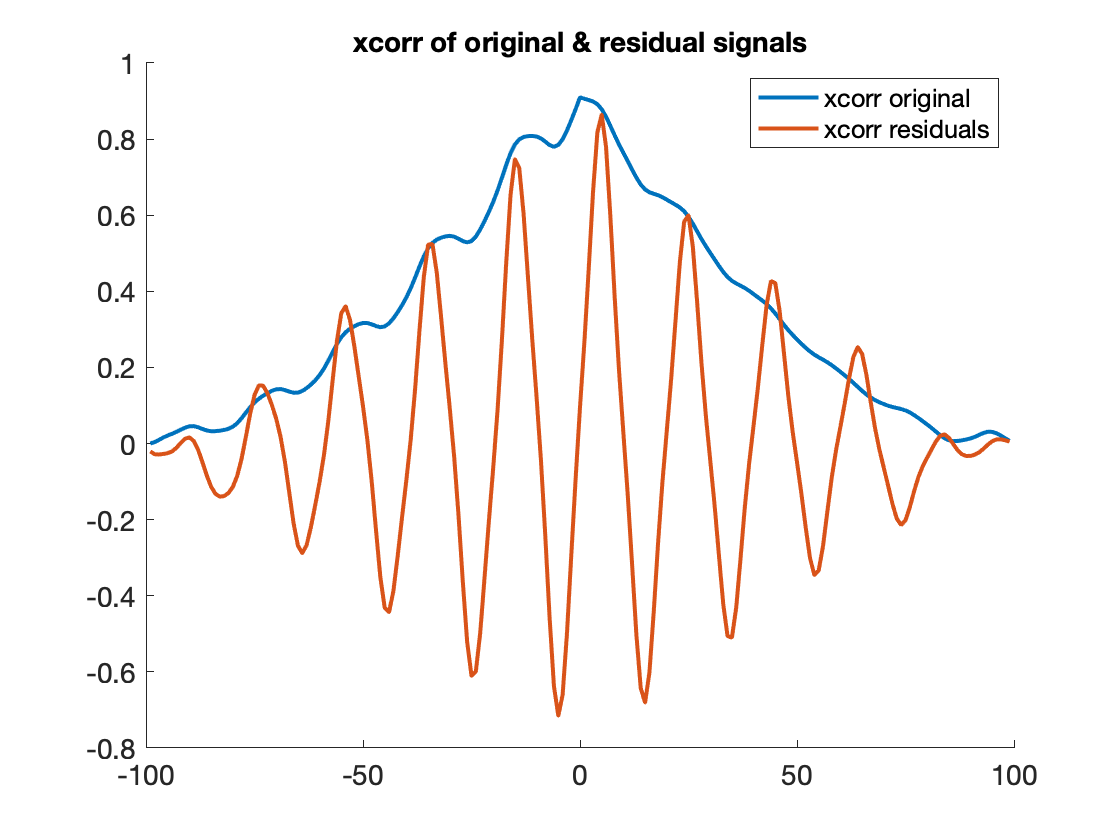


% Plot xcorr for original signals and signals without the moving average
figure(3); clf; hold on;
[xc_orig, lags_orig]= xcorr(y1, y2, 'coeff'); plot(lags_orig, xc_orig); title('xcorr of original & residual signals')
[xc_res, lags_res]= xcorr(y1-mn_1, y2-mn_2, 'coeff'); plot(lags_res, xc_res); 
legend('xcorr original', 'xcorr residuals')


[mx_orig, ind_orig] = max(xc_orig);
[mx_res, ind_res] = max(xc_res);

fprintf('True offset of signals is %0.02fpi', offset/pi);

True offset of signals is 0.50pi

fprintf('Max correlation of original (non stationary) signals is %0.2f at %0.02fpi lag', mx_orig, .1*lags_orig(ind_orig))

Max correlation of original (non stationary) signals is 0.91 at 0.00pi lag

fprintf('Max correlation of residual signals is %0.2f at %0.02fpi lag', mx_res, .1*lags_res(ind_res))

Max correlation of residual signals is 0.86 at 0.50pi lag

Notice how the original signals always have a max correlation at zero lag, whereas cross correlation of the residuals shows the maximum correlation to be at a lag of 0.5pi, which is  the offset that we originally added. 

## How does signal smoothing impact correlation?

One of the other questions we might ask is about how much smoothing of our signal would affect the correlation. First, the reason for applying the smoothing is because there may be some underlying randomness or noise that is obscuring our signal of interest.

So how does our smoothing choice effect correlation?

Say we have two of the same sine waves with different noise added, and we smooth them using a moving average. Without noise, the zero lag correlation between them should be 1. How do the correlations of the smoothed and noisy signals compare? 

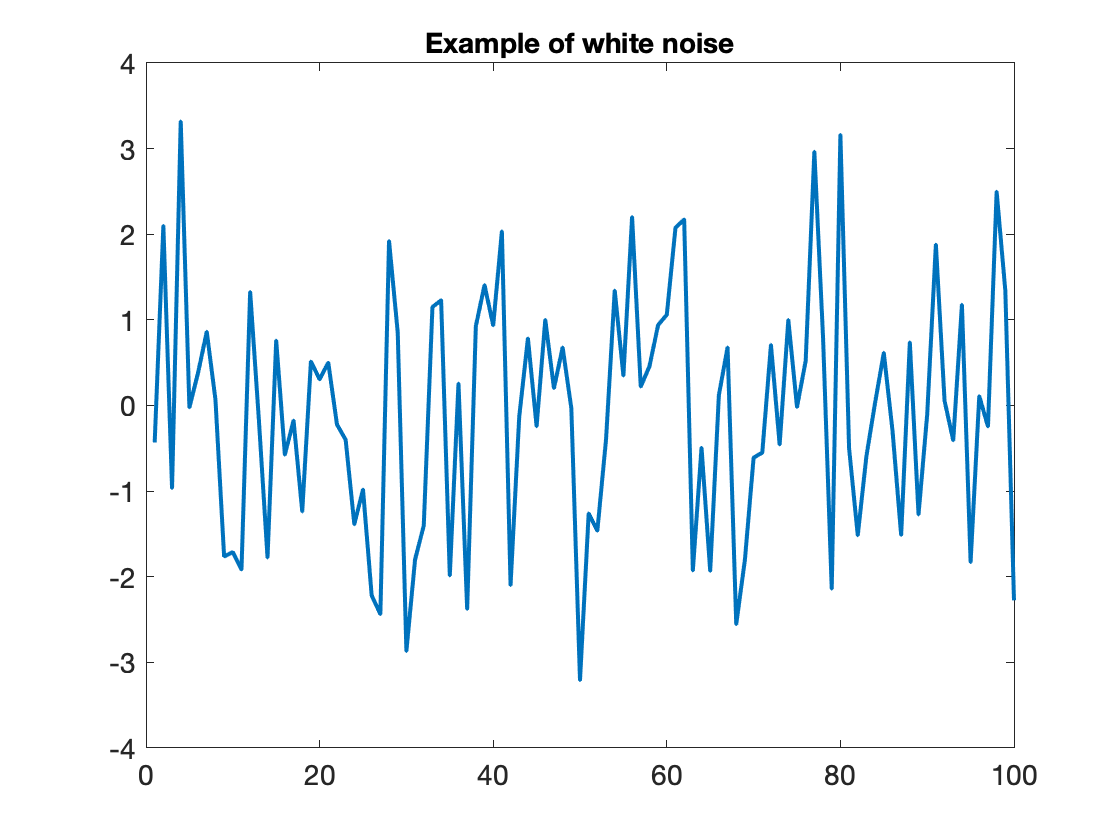

% Note: since "wgn" pulls noise from a random distribution, I'm settting the randomization
% "seed" in matlab so that everytime this section is run, the same random white noise 
% signal is generated:
rng(5);  

figure(2); clf; plot(wgn(1,100,2)); title('Example of white noise');

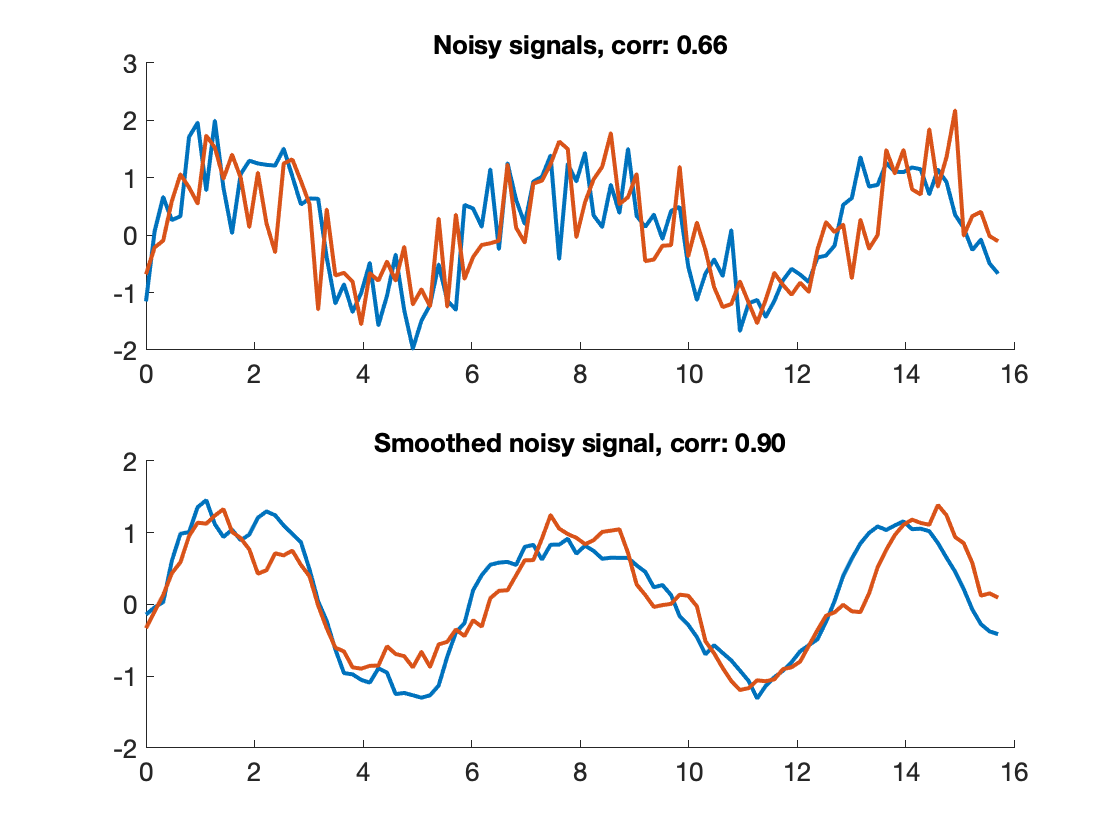


x=linspace(0,5*pi); 
y1= sin(x)+ wgn(1, length(x), 1)/2; % Note: wgn creates a vector of white noise, which I'm combining with the sine wave
y2= sin(x)+ wgn(1, length(x), 1)/2;

smooth_wind = 5; % How many windows of smoothing

y1_smooth = movmean(y1, smooth_wind);
y2_smooth = movmean(y2, smooth_wind);

figure(1); clf; 
subplot(211); hold on; plot(x,y1); plot(x,y2); title(sprintf('Noisy signals, corr: %0.2f', corr(y1', y2')))
subplot(212); hold on; plot(x, y1_smooth); plot(x, y2_smooth); title(sprintf('Smoothed noisy signal, corr: %0.2f', corr(y1_smooth', y2_smooth')))

In this example, more smoothing reduces the noise so that we can get at the underlying "true" signal, and get closer to the correlation of 1. There are some caveats when applying this to the real world: Smoothing can sometimes get rid of the more delicate parts of the signal that are actually informative and maybe aren't noise. If you think about it, in the extreme case where you increase the size of your moving average window to include the entire signal, you will end up with a single value: the mean of the signal. It is helpful if the choice of window size is logically motivated (such as the 7-day moving average for COVID cases). 